Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# 3D-geometry of a beam line (Section 2.1)

Volker Ziemann, 211123

In this example we discuss a program the produce the three-dimensional layout of an accelerator. It produces a top view of the beamline or ring and writes an input file for the solid-modeling program OpenSCAD, which is available from   [https://openscad.org.](https://openscad.org.) It also maintains a list of start and end coordinates of each element in the laboratory frame.

As an example, let us define a ring that consists of a sequence of quadrupole and dipole magnets known as a FODO lattice. We define one FODO cell as a sequence of element, distinguished by their code, which is the entry in the first column of the following array `fodo,` where code =1 indicates a beam pipe, code=5 indicates a quadrupole, and code=4 indicates dipole magnet. The second column denotes how many times the same element should be repeated, which is not used here, but is convenient later in the book. The third column indicates the length of the element and the fourth column its strength. We will use this format to describe beam lines throughout the book. In this example the only interesting parameter in the fourth column is the deflection angle of the dipole magnet, because it changes the direction of the reference system. The quadrupole excitations are not used here, because they do not change the direction of the reference orbit.

clear;
fodo=[ 1  1  2.5  0 ; 
       5  1  1.0  0.0777;   % quadrupole
       1  1  1.5  0 ; 
       4  1  2.0  30;       % dipole
       1  1  1.5  0; 
       5  1  1.0  -0.1472;  % quadrupole
       1  1  2.5  0;]; 

Having defined the fundamental cell with a 30-degree dipole, we realize that we need twelve cells to construct a whole ring. The resulting array is called beamline. We also count the number of lines and elements. The latter is needed, if we had used repeat codes in the scond column that differ from unity.

beamline=repmat(fodo,12,1);
nlines=size(beamline,1);       % number of lines
nele=sum(beamline(:,2))+1;     % number of elements

The next lines allocate space for the coordinates `vvpos()` of the elements in beamline, set the origin `vv` where we start and the direction `ww`, which is specified by a rotation matrix. It is easy to visualize vv and ww as the location of the reference particle and its direction of travel; the columns of the matrix ww denote the three unit vectors that define a tripod that "rides on the reference particle."  

vvpos=zeros(3,nele);           % element positions
vv=[0;0;0];                    % x,y,z or origin
ww=eye(3);                     % orientation of tripod

Now we open a file with the name `layout.scad` to which we write OpenSCAD commands that create the 3D geometry. We also specify 'hold on' in order to add elements to the MATLAB plot with the top view onto the ring.

f=fopen('layout.scad','w');    % open output file for 3D view
hold on                        % can add elements to the same plot

After inilializing the element counter `ic`, we loop over the lines and segments in the `beamline`.

ic=1;                          % element counter
for line=1:nlines              % loop over input elements
  for seg=1:beamline(line,2)   % loop over repeat-count

Inside the loop, we record the position `v0` and orientation `w0` of the previous point, update the lement counter` ic`, and check the code in the first column of `beamline` of the presently considered element. If it is an element that does not change the direction of the particle, such as drift spaces, quadrupoles, or solenoids, we only record by how much the position advances in `dv`, and note that the orientation stays the same with `dw`.

    v0=vv; w0=ww;              % remember previous point
    ic=ic+1;                     
    switch beamline(line,1)  
      case {1,2,5,7}   % drift, quadrupole, solenoid
        dv=[0;0;beamline(line,3)]; 
        dw=eye(3);

If the element is a dipole magnet and the deflection angle is non-zerom we calculate its bending radius rho and update the position with` dv` along the sagitta of the trajectory in the magnet. The orientation of the coordinate system changes by the angle phi around the vertical axis, where we use `wmake()`, defined in the Appendix, to create the rotation matrix. For the OpenSCAD file we also need the rotation with half the angle phi. Note that if the rotation angle is less than $10^{-7}$ radians the element is treated as straight element.

      case 4           % sector dipole
        phi=beamline(line,4)*pi/180;  % convert to radians
        if abs(phi)>1e-7
          rho=beamline(line,3)/phi;                 % bending radius
          dv=[rho*(cos(phi)-1);0.0;rho*sin(phi)];   % sagitta
          dw=wmake(0,-phi,0);
          dw2=wmake(0,-phi/2,0); % for 3D renderer only
        else
          dv=[0;0;beamline(line,3)]; 
          dw=eye(3); 
        end 

Occasioanlly, we need a coordinate rotation, for example to make a vertically deflecting dipole by sandwiching a horizontally deflecting dipole between two $90^o$ rotations with opposite sign. If an element with unknown code in the first column appears, a short warning is displayed and neither position nor orientation are changed.

      case 20   % coordinate rotation
        dv=[0;0;0];
        dw=wmake(0,0,beamline(line,4)*pi/180);
      otherwise
        disp('unsupported code')
        dv=[0;0;0]; dw=eye(3);
    end

After setting up the differential changes of position `dv` and orientation `dw`, we use them to update the corresponding absolute values `vv` and `ww`, which are defined at the end point of the currently considered element.

    [vv,ww]=wprop(vv,ww,dv,dw);
    vvpos(:,ic)=vv';

Now it's time to add the elements to the top-down view and the OpenSCAD model, which we do for dipoles with code 4 and for quadrupoles with code 5 in the following switch statement.

    switch beamline(line,1)      

In the case statement for the dipole the drawbox() command plots the blue rectangle at the position an orientation of the magnet in the Matlab figure. The call to draw3D() places a blue box and a pedestal in the OpenSCAD model. 

      case 4   % sector dipole
        drawbox(vv,v0,0.5,'b'); 
        draw3D(f,v0,w0*dw2,[1.,0.6,beamline(line,3)],[0,0,1]);

Likewise does the following section place a red rectangle in the Matlab figure and a red box on a pedestal.

      case 5   % quadrupole
        drawbox(vv,v0,0.7,'r');
        draw3D(f,v0,w0,[0.8,0.8,beamline(line,3)],[1,0,0]);

in all other places we place a grey cylinder, illustrating the beam pipe, into the OpenSCAD model.

      otherwise % draw beampipe
        draw3Dpipe(f,v0,w0,0.05,beamline(line,3));     
    end
  end
end

After all magnets are placed into the figure and the OpenSCAD model, we draw a thick black line into the Matlab figure that follows the position of the reference particle, or equivalently, the center f the beam pipe. The we ensure that the scale in both x and z direction are equal and annotate the axes.

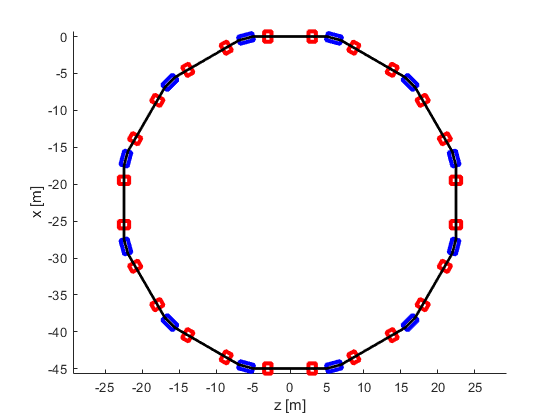

plot(vvpos(3,:),vvpos(1,:),'k','LineWidth',2);
axis equal
xlabel('z [m]'); ylabel('x [m]');

In the last step we place a solid grey slab under the OpenSCAD model and close the OpenSCAD file.

fprintf(f,'color([0.99,0.99,0.99]) translate([-75,-1.5,-50])');
fprintf(f,'cube([100,0.2,100]);');
fclose(f);
%system('openscad layout.scad &')

We can explore the OpenSCAD model by first installing the openscad program and the opening `layout.scad` from the menu or from the command line with `openscad layout.scad.` The following image shows the geometry rendered in opescad.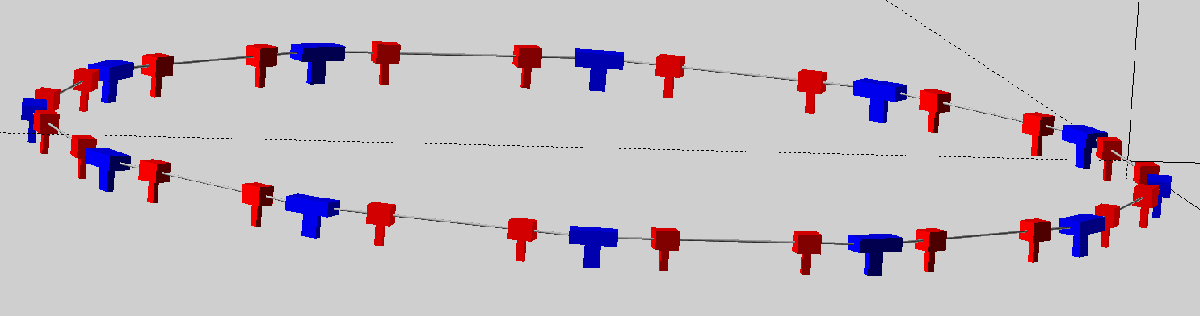

## Appendix

#### wmake()

The function `wmake()` receives the three angles `phix, phiy,` and `phiz` as input and returns the product `dw` of the three rotation matrices around the x, y, and z-axis, respectively.  Inside the function the three rotation matrices are constructed and multiplied.

function dw=wmake(phix,phiy,phiz)
wx=eye(3); 
wx(2,2)=cos(phix); wx(3,3)=wx(2,2);
wx(2,3)=sin(phix); wx(3,2)=-wx(2,3);
wy=eye(3); 
wy(1,1)=cos(phiy); wy(3,3)=wy(1,1);
wy(1,3)=sin(phiy); wy(3,1)=-wy(1,3);
wz=eye(3);
wz(1,1)=cos(phiz); wz(2,2)=wz(1,1);
wz(1,2)=sin(phiz); wz(2,1)=-wz(1,2);
dw=wx*wy*wz;
end

#### wprop()

The function `wprop()` receives the position `vv` and orienation `ww` at the start of an element, as well as the change in position `dv` and orientation `dw` as input. It then returns the position `vnew` and orienation `wnew` at the exit of that element. 

function [vnew,wnew]=wprop(vv,ww,dv,dw)
vnew=vv+ww*dv;
wnew=ww*dw;
end

#### drawbox()

The function `drawbox()` reveives the starting position `v0` and the end position `v` of an element, as well as its `width` and `color`, specified as an array with` [r,g,b]` values, where `r,g,b` are number between 0 and 1. The function the draws a box in the current figure.

function drawbox(v0,v,width,color)
box=zeros(2,6);
tmp=hypot(v(3)-v0(3),v(1)-v0(1));
if tmp > 1e-8
    p=[v(3)-v0(3),0,-(v(1)-v0(1))]/tmp;
    box(:,1)=[v0(3),v0(1)];
    box(:,2)=[v0(3)+p(3)*width,v0(1)+p(1)*width];
    box(:,3)=[v(3)+p(3)*width,v(1)+p(1)*width];
    box(:,4)=[v(3)-p(3)*width,v(1)-p(1)*width];
    box(:,5)=[v0(3)-p(3)*width,v0(1)-p(1)*width];
    box(:,6)=[v0(3),v0(1)];
end
plot(box(1,:),box(2,:),color,'LineWidth',3);
end

#### draw3Dpipe()

The function `drawPipe()` receives a file handle` f`, the start position `v0` and orientation `w0`, as well as the `radius` and the `length` as input and places a grey cylinder into the OpenScad model in file` f`.

function draw3Dpipe(f,v0,w0,radius,len)
fprintf(f,'multmatrix([ [ %f , %f , %f , %f ],\n',w0(1,1),w0(1,2),w0(1,3),v0(1));
fprintf(f,'   [ %f , %f , %f , %f ],\n',w0(2,1),w0(2,2),w0(2,3),v0(2));
fprintf(f,'   [ %f , %f , %f , %f ],\n',w0(3,1),w0(3,2),w0(3,3),v0(3));
fprintf(f,'   [ %f , %f , %f , %f ] ])\n',0,0,0,1);
fprintf(f,'translate([%f,%f,%f])\n',0,0,len/2);
fprintf(f,'color([0.7,0.7,0.7])\n');
fprintf(f,'cylinder($fn=30, h=%f,r=%f,center=true);\n',len,radius);
end

#### draw3D()

The function draw3D() receives a file handle f, the start position vo and orienation w0 of a `box`, which is specified by its three dimensions. The last argument specifies the `color` of the element that is placed into the OpenSCAD model. One box is produces for the magnet and one for the pedestal below it.

function draw3D(f,v0,w0,box,color)
fprintf(f,'multmatrix([ [ %f , %f , %f , %f ],\n',w0(1,1),w0(1,2),w0(1,3),v0(1));
fprintf(f,'   [ %f , %f , %f , %f ],\n',w0(2,1),w0(2,2),w0(2,3),v0(2));
fprintf(f,'   [ %f , %f , %f , %f ],\n',w0(3,1),w0(3,2),w0(3,3),v0(3));
fprintf(f,'   [ %f , %f , %f , %f ] ])\n',0,0,0,1);
fprintf(f,'translate([%f,%f,%f])\n',-box(1)/2,-box(2)/2,0);
fprintf(f,'color([%f,%f,%f]){\n',color(1),color(2),color(3));
fprintf(f,'cube([%f,%f,%f]);\n',box(1),box(2),box(3));
fprintf(f,'translate([%f,%f,%f]) ',box(1)/2,-0.5,box(3)/2);
fprintf(f,'cube([%f,%f,%f],center=true);}\n',box(1)/3,1,box(3)/3);
end